%DATA_FILEPATH = "/Users/siddhantgupta/Documents/MATLAB/ece113dw_project/audio_data"
DATA_FILEPATH = "C:\Users\tim\Documents\MATLAB\ECE113\ece113dw_project\audio_data";

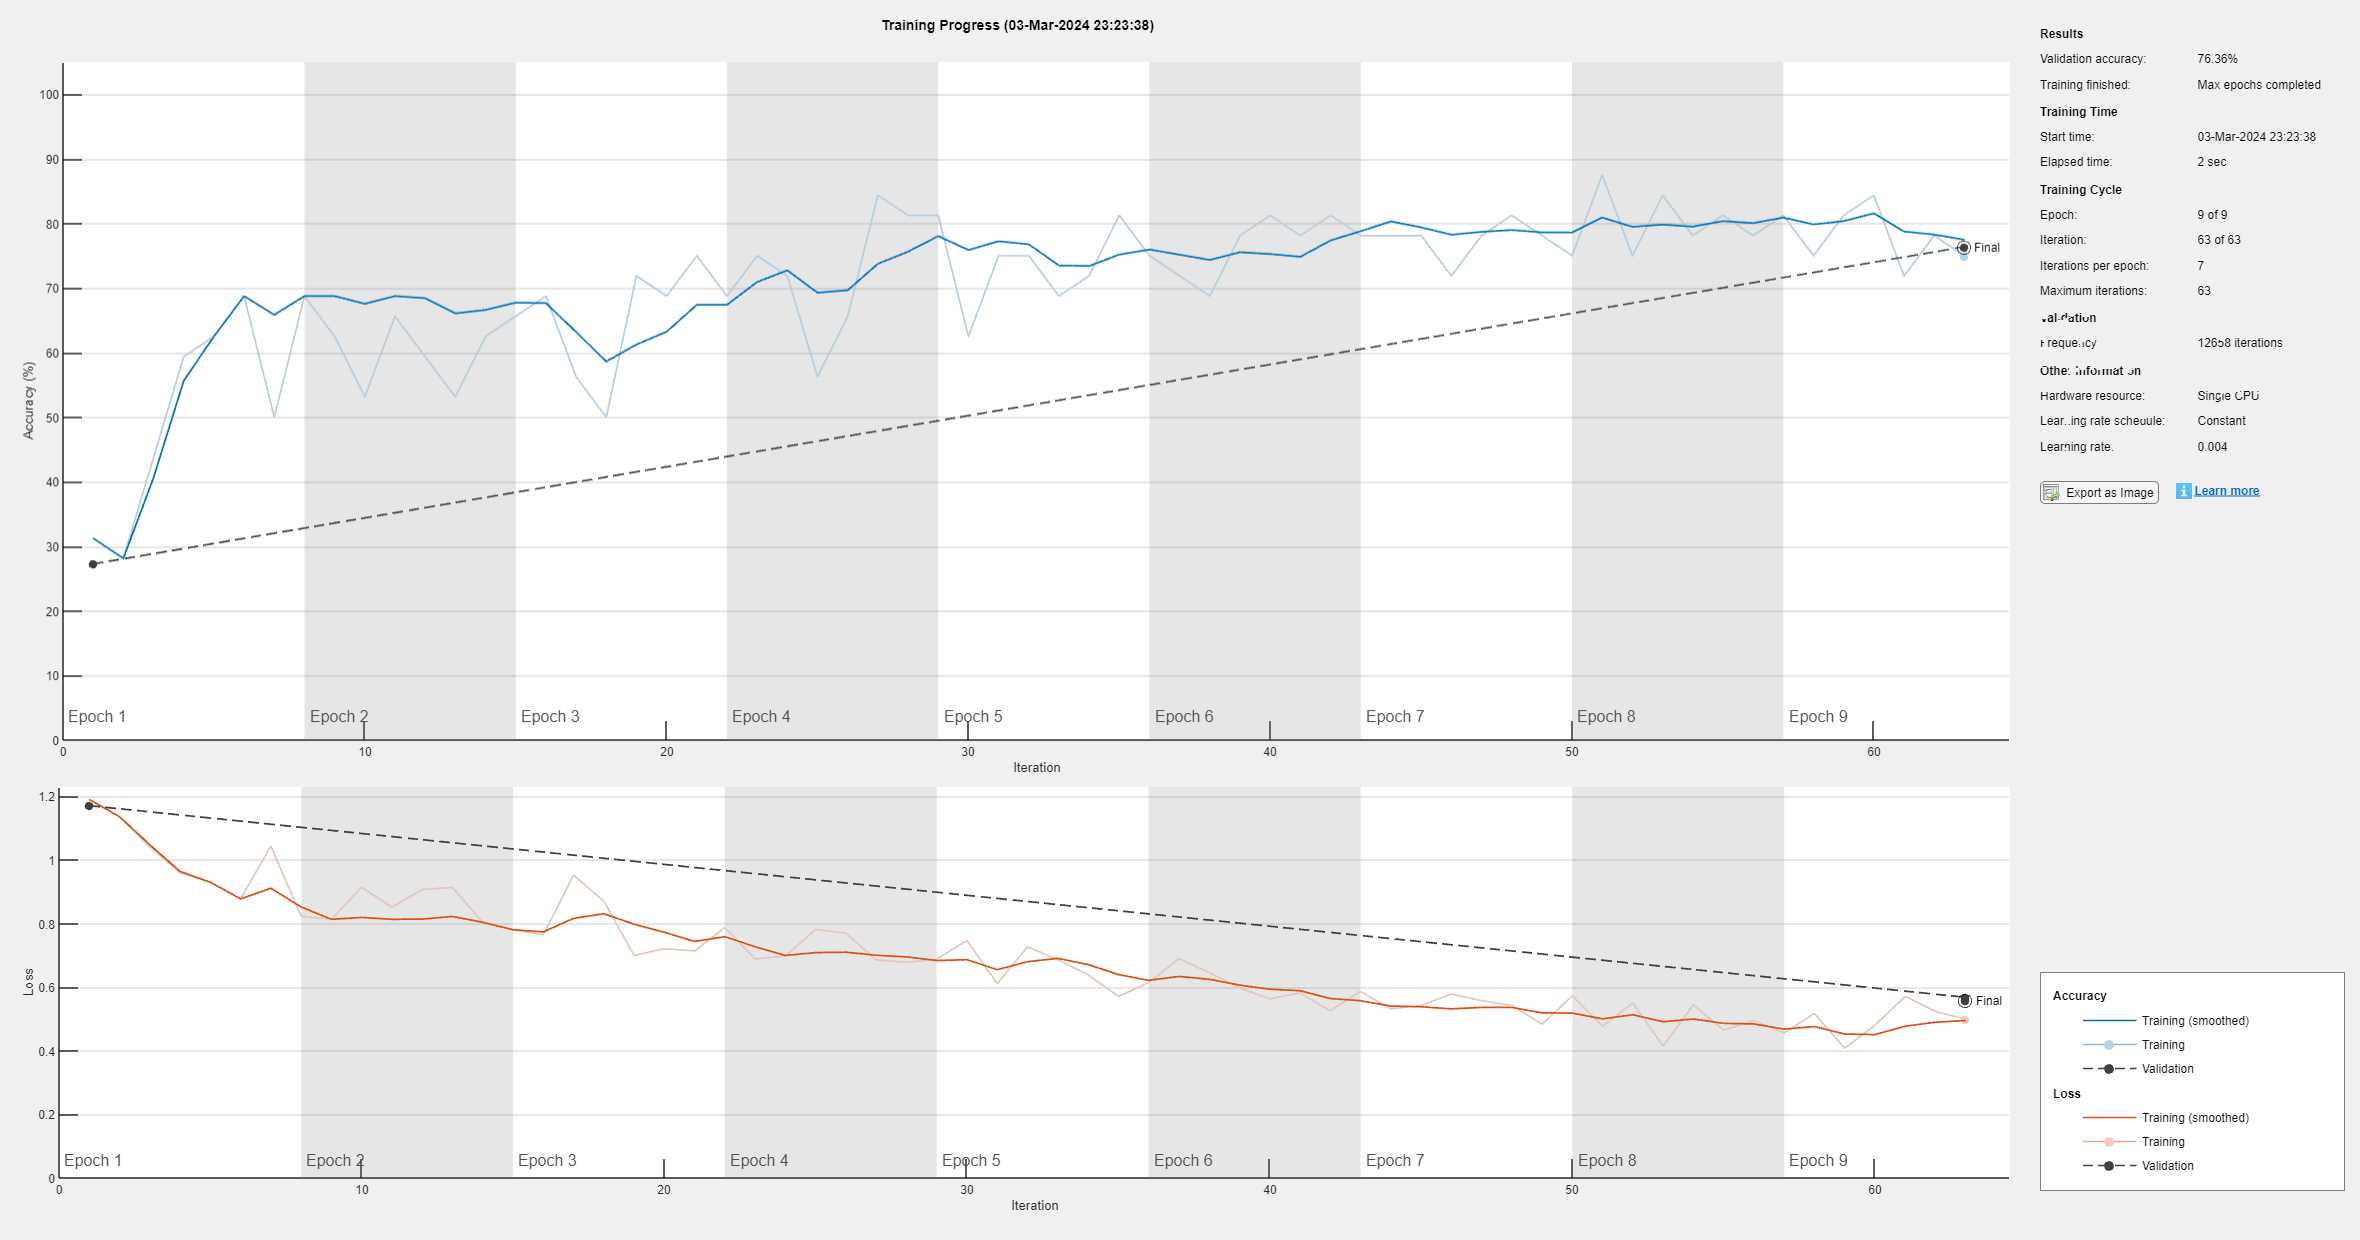

    "Training error: 20.2429 %"
    "Validation error: 23.6364 %"



results_stored =     0.2364    1.0000         0         0  256.0000   64.0000   40.0000


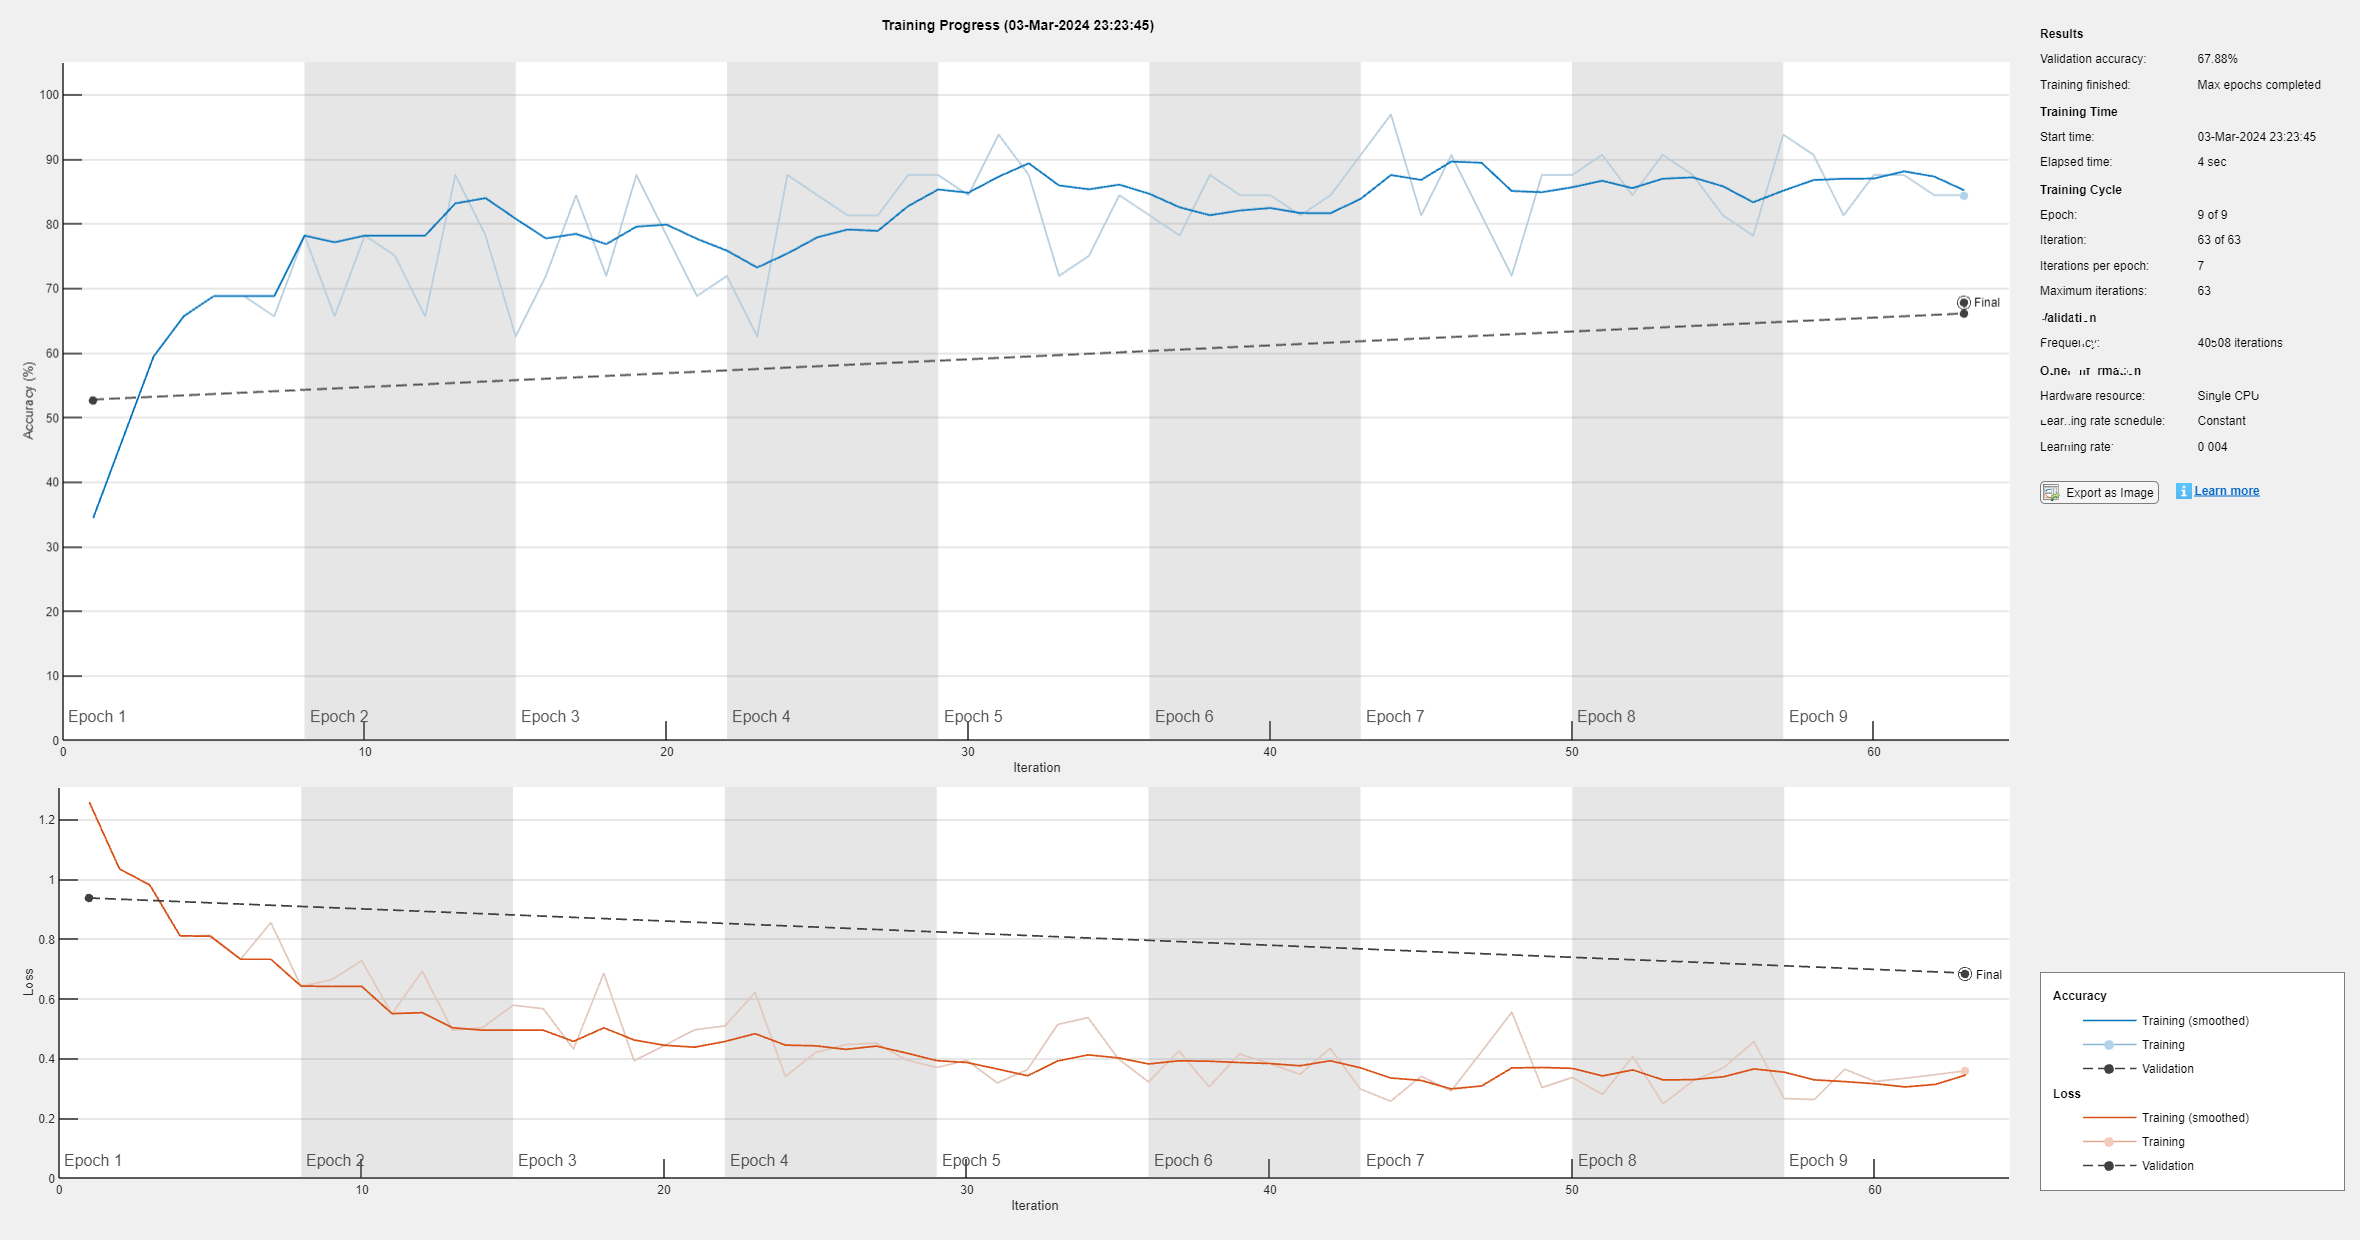

    "Training error: 13.3603 %"
    "Validation error: 32.1212 %"



results_stored =     0.2364    1.0000         0         0  256.0000   64.0000   40.0000    0.3212    1.0000         0         0  256.0000   64.0000  128.0000


% Parameters to grid search
melSpectrum = [true];
mfccs = [false];
mfcc_deltas = [false];
win_sizes = [ 256 ]; % in number of samples (64 ms = 512 samples)
overlap_proportion = [4];
numBands = [ 40, 128 ];
results_stored = [];
confusion_stored = [];
for melSpectrum_t = melSpectrum
    for mfccs_t = mfccs
        for mfcc_deltas_t = mfcc_deltas
            for win_sizes_t = win_sizes
                for overlap_proportion_t = overlap_proportion
                    for numBands_t = numBands

%begin grid search code
                        
                        [results, confusion ]= trainAndReport(DATA_FILEPATH, melSpectrum_t, mfccs_t, mfcc_deltas_t , win_sizes_t, ...
                          floor(win_sizes_t/overlap_proportion_t) ,  numBands_t);
                        results_stored = [results_stored, results]
                        confusion_stored = [confusion_stored , confusion];



                    end

                end

            end

        end

    end
end

function [results, confusion] = trainAndReport(DATA_FILEPATH, USE_MELSPECTRUM, USE_MFCC, USE_MFCC_DELTA , win_sizes_t, ...
    overlap, num_bands)
    % Create datastore
    %DATA_FILEPATH = "/Users/siddhantgupta/Documents/MATLAB/ece113dw_project/audio_data";%"ECE113/ece113dw_project/audio_data";

    dataset = fullfile(DATA_FILEPATH);
    
    ads = audioDatastore(dataset, ...
        IncludeSubfolders=true, ...
        FileExtensions=".wav", ...
        LabelSource="foldernames");
    
    % Split into train / test
    
    [train,test] = splitEachLabel(ads,0.6,'randomize');
    
    % Extract Features
    afe = audioFeatureExtractor( ...
        SampleRate=8000, ...
        FFTLength=256, ...
        Window=hamming(win_sizes_t,"periodic"), ...
        OverlapLength=overlap, ...
        melSpectrum=USE_MELSPECTRUM, mfcc=USE_MFCC, ...
        mfccDelta=USE_MFCC_DELTA);
    if(USE_MELSPECTRUM)
        setExtractorParameters(afe,"melSpectrum",NumBands=num_bands,WindowNormalization=false);
        setExtractorParameters(afe,"melSpectrum",SpectrumType="magnitude")
    end
    if(USE_MFCC)
        setExtractorParameters(afe,"mfcc",NumCoeffs=13);
    end
    [results, confusion] = trainModel(afe, train, test);
    results = [results, USE_MELSPECTRUM, USE_MFCC, USE_MFCC_DELTA , win_sizes_t, ...
    overlap, num_bands];

end

function [results, confusion ]= trainModel(afe, train , test)
    train_d = extract(afe,train);
    test_d = extract(afe,test);
    
    % Read in data
    %train_d = readall(train_tf);
    %test_d = readall(test_tf);
    
    train_d = cat(4,train_d{:});
    test_d = cat(4,test_d{:});
    [numHops,numBands,numChannels,numFiles] = size(train_d);
    
    % Separate Labels
    train_labels = train.Labels;
    test_labels = test.Labels;
    
    % Define model
    classes = categories(train_labels);
    num_classes = numel(classes);
    num_filters = 2;
    
    layers = [
        imageInputLayer([numHops,afe.FeatureVectorLength])
        
        convolution2dLayer(5,num_filters,'Padding','same')
        batchNormalizationLayer
        reluLayer
        
        maxPooling2dLayer(2,'Stride',2)
        
       convolution2dLayer(5,num_filters,'Padding','same')
         batchNormalizationLayer
        reluLayer
        
        maxPooling2dLayer(2,'Stride',2)
        
        convolution2dLayer(3,num_filters,'Padding','same')
        batchNormalizationLayer
        reluLayer
        
        fullyConnectedLayer(num_classes)
        softmaxLayer
        classificationLayer(Classes=classes)];
    % Train model
    miniBatchSize = 32;
    validationFrequency = floor(numel(train_d)/miniBatchSize);
    options = trainingOptions("adam", ...
        InitialLearnRate=4e-3, ...
        MaxEpochs=9, ...
        MiniBatchSize=miniBatchSize, ...
        Shuffle="every-epoch", ...
        Plots="training-progress", ...
        Verbose=false, ...
        ValidationData={test_d,test_labels}, ...
        ValidationFrequency=validationFrequency);
    
    trainedNet = trainNetwork(train_d,train_labels,layers,options);
    test_pred = classify(trainedNet,test_d);
    validationError = mean(test_pred ~= test_labels);
    train_pred = classify(trainedNet,train_d);
    trainError = mean(train_pred ~= train_labels);
    
    disp(["Training error: " + trainError*100 + " %";"Validation error: " + validationError*100 + " %"])
    figure(Units="normalized",Position=[0.2,0.2,0.5,0.5]);
    %cm = confusionchart(test_labels,test_pred, ...
   %     Title="Confusion Matrix for Validation Data", ...
   %     ColumnSummary="column-normalized",RowSummary="row-normalized");
    C = confusionmat(test_labels, test_pred);
    results = validationError;
    confusion = C;
end
